**Partiel automatique Mathieu Dreyer**

Exercice 1 : 

Question 1 :

Les paramètres de la fonction de transfert sont : 

t = 0.25, en seconde

K = (310-260) / 5, en radian par seconde par V

K = (310-260) / 5 ; %gain statique, en radian par seconde par V

Vitesse atteinte : 310rad/s

Donc tour par minutes = 2960,28

Question 2 :

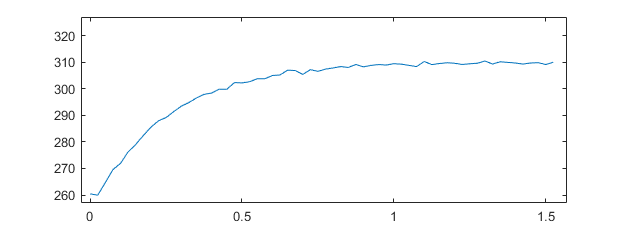

s = tf('s');
Tbo = 0.25;
tfinal = 1.5; 
t = (0:Te:tfinal + Te);
plot(t,S)
sys = K / (1 + Tbo * s);
xlim([-0.03 1.57])
ylim([257.0 327.0])

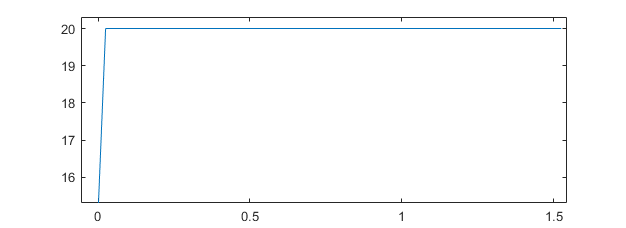

plot(t,U);

xlim([-0.056 1.544])
ylim([15.31 20.31])

*Question 3 :*

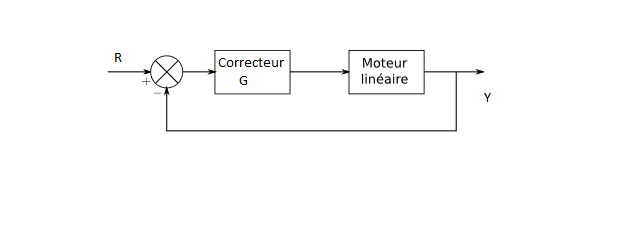

figure;
imshow("schema_bloc.png");

Question 4 :

Hbf = sys / (1+sys);


$$\begin{array}{l}
Y\left(s\right)=K*\left(\;X\left(s\right)-Y\left(s\right)\right)*\frac{1}{1+s*T}\\
Y\left(s\right)*\left(1\;+\frac{K}{1+s*T}\right)=\frac{K}{1+s*T}*X\left(s\right)\\
H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}=\frac{K}{1+K+s*T}\\
\mathrm{Donc}\;G\left(0\right)=\frac{K}{1+K}\;\mathrm{et}\;\tau =\frac{T}{1+K}
\end{array}$$


Kbf = K / (1 + K);
Tbf = Tbo / (1 + K);


Question 5 :

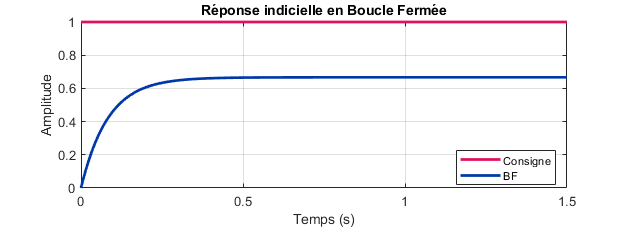

g = 0.2;
cor = g;
sysbf=feedback(cor*sys,1); % résultat FT
tech=(0:Te:tfinal)';
[yech]=step(1,1,tech); %step(u0,sys,tech)

[ybf,tbf]=step(sysbf,tfinal);
plot(tech,yech,'LineStyle','-','Color','#E0115F','LineWidth',2);% red et 'LineStyle','none'
grid,hold on
plot(tbf,ybf,'MarkerFaceColor','#0038A8','LineStyle','-','Color','#0038A8','LineWidth',2); % blue
xlabel('Temps (s)')
ylabel('Amplitude')
title(['Réponse indicielle en Boucle Fermée'])
legend('Consigne','BF','Location','best')
hold off

On remarque que l'on atteinds jamais la consigne, mais le régime permanant est atteinds plus rapidement (0.2 s contre 1 s avant)

Question d'application de cours :

***Question 1 : Que représentent le gain statique et la constante de temps d’une fonction de transfert***


$$H\left(\rho \right)=G*\frac{1}{1+\tau p}$$


Le gain statique d'un système progressivement stable est défini par le rapport entre la sortie en régime permanent et l'entrée (lorsque celle-ci est une étape), soit le gain en régime permanant.   Il s'agit d'un coefficient K propre au système qui permet de déterminer la nouvelle valeur stable de la mesure (M1) suite à un échelon. (G)

$\tau$ est la constante de temps (s), elle est positive.

***Question 2 Expliquez l’intérêt d’une boucle fermée.***

L'interet d'une boucle fermée est que celle ci prends en compte la sortie, contrairement à une boucle ouverte.

***Question 3 Expliquez les différences entre les modes manuel et automatique d’un régulateur industriel.***

 En mode manuel : stabiliser la mesure au point de consigne manuellement.

En mode auto : amene l'entrée à la valeur de sa sortie manuelle.

***Question 4 : Quel est le rôle d’un correcteur ?***

Un correcteur dispose de plusieurs roles : 

- réduire l’effet des perturbations.

- filtrer ou au moins ne pas amplifier les bruits de mesure.

Il permet de réduire la sensibilité aux variations paramétriques du système et de prendre en compte des incertitudes paramétriques.

***Question 5 : Quel est l’intérêt d’un modèle de référence ?***

L'interet d'un modèle de réference est de faire en sorte que l’écart entre la sortie et la consigne tende vers 0 en régime permanent.

***Question 6 : Sous quelle forme est implantée la dérivée dans un régulateur industriel?***

***Question 7 : Donnez l’ordre de la fonction de transfert suivante : ***$\frac{Y\left(s\right)}{U\left(s\right)}=\frac{1+s}{\left(1+2s\right)\left(3+9s\right)}\;$*** . ***

***Calculez son gain statique, ou ses constante(s) de temps ou ses zéros.***

$\frac{Y\left(s\right)}{U\left(s\right)}=\frac{1+s}{\left(1+2s\right)\left(3+9s\right)}$ = $\frac{2}{3\left(3s+1\right)}-\frac{1}{3\left(2s+1\right)}$

[z,g] = zero((1+s)/((1+2*s)*(3+9*s)))

z = -1

g = 0.0556

Zéros : 

-   s = -1

Poles : 

-    x = -1/2 = -0.500

-    x = -1/3 = -0.333

Constantes de temps : 0

Gain statique : 0.0556